testPath1 = fullfile("\\islfs01.hlm.ad.moffitt.usf.edu\UsersL$\4470641\Desktop","sko2_2951(10).qptiff - resolution #1 (1, x=5304, y=7653, w=5463, h=3561).tif");
testImage1 = imread(testPath1);
[stainMatrix1, stainConc1] = estimatestaining(testImage1)

stainMatrix1 =     0.6573    0.1520
    0.6976    0.9431
    0.2852    0.2956


stainConc1 =     1.3268
    0.9134



testPath2 = fullfile("M:\lab\Lab_Flores\transfer\SharedFolder_082916\Shared Folder\CurrentLabMembers\Jay Lockhart\Projects\01_Machine Learning\01_GLASS-AI\99_Application installers\Demo Data","20patch.tif");
testImage2 = imread(testPath2);
[stainMatrix2, stainConc2] = estimatestaining(testImage2)

stainMatrix2 =     0.6678    0.1707
    0.6717    0.8963
    0.3208    0.4094


stainConc2 =     2.4208
    1.1570



outFilePath = "\\islfs01.hlm.ad.moffitt.usf.edu\UsersL$\4470641\Desktop\StainNormTesting";

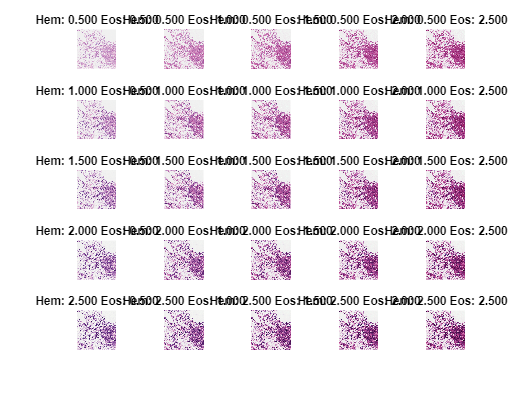


HemConcStepStart = 0.5;
HemConcStepStop = 2.5;
HemConcStepSize = 0.5;
HemStepCount = length(HemConcStepStart:HemConcStepSize:HemConcStepStop);

EosConcStepStart = 0.5;
EosConcStepStop = 2.5;
EosConcStepSize = 0.5;
EosStepCount = length(EosConcStepStart:EosConcStepSize:EosConcStepStop);

testImage = testImage2;
testStainMatrix = stainMatrix2;
testStainConc = stainConc2;
HemInc = 0;
EosInc = 0;

imageMatrix = cell(HemStepCount,EosStepCount);
figure
tiledlayout(HemStepCount,EosStepCount,"TileSpacing","tight")

for HemConc = HemConcStepStart:HemConcStepSize:HemConcStepStop
    HemInc = HemInc + 1;
    EosInc = 0;
    for EosConc = EosConcStepStart:EosConcStepSize:EosConcStepStop
        EosInc = EosInc + 1;
        imageMatrix{HemInc, EosInc} = applystainnormalization(testImage,testStainMatrix,testStainConc,Io = 240,referenceStainConc = [HemConc; EosConc]);

        nexttile
        imshow(imageMatrix{HemInc, EosInc})
        title(sprintf("Hem: %0.3f Eos: %0.3f",HemConc,EosConc))
        outFileName = sprintf("Hem_%0.3f_Eos_%0.3f.tif",HemConc,EosConc);
         
        imwrite(imageMatrix{HemInc, EosInc},fullfile(outFilePath,outFileName));
    end
end